# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

.                       computeCostMulti.m      ex1data1.txt            gradientDescent.m       normalEqn.m             token.mat               
..                      ex1.mlx                 ex1data2.txt            gradientDescentMulti.m  plotData.m              warmUpExercise.m        
computeCost.m           ex1_companion.mlx       featureNormalize.m      lib                     submit.m                



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

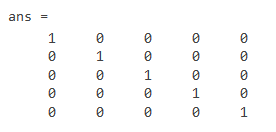

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

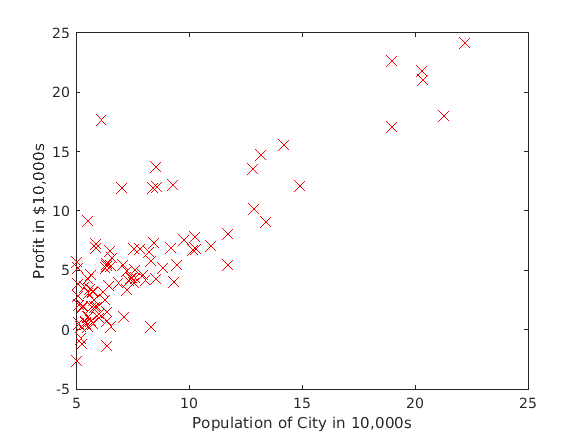

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

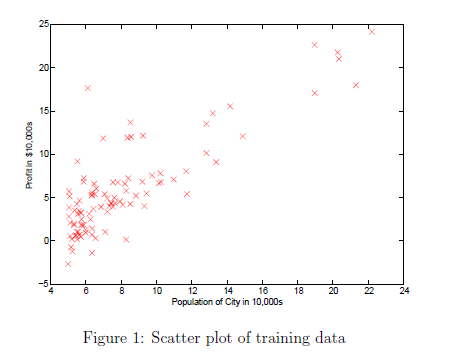

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X) % number of training examples

m = 97

X = [ones(m, 1), data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

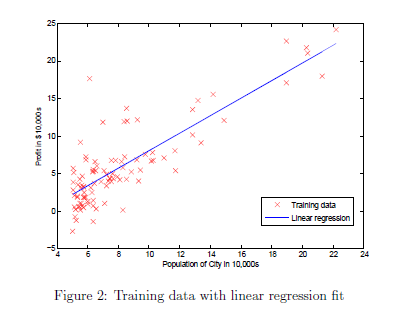    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

n = 2

t = 0.7201

t =     0.7201
    0.7293


n = 2

t =     0.7118
    0.7293


t =     0.7118
    0.7302


n = 2

t =     0.7035
    0.7302


t =     0.7035
    0.7310


n = 2

t =     0.6952
    0.7310


t =     0.6952
    0.7318


n = 2

t =     0.6869
    0.7318


t =     0.6869
    0.7327


n = 2

t =     0.6787
    0.7327


t =     0.6787
    0.7335


n = 2

t =     0.6704
    0.7335


t =     0.6704
    0.7343


n = 2

t =     0.6622
    0.7343


t =     0.6622
    0.7351


n = 2

t =     0.6540
    0.7351


t =     0.6540
    0.7360


n = 2

t =     0.6458
    0.7360


t =     0.6458
    0.7368


n = 2

t =     0.6376
    0.7368


t =     0.6376
    0.7376


n = 2

t =     0.6294
    0.7376


t =     0.6294
    0.7384


n = 2

t =     0.6212
    0.7384


t =     0.6212
    0.7392


n = 2

t =     0.6131
    0.7392


t =     0.6131
    0.7401


n = 2

t =     0.6050
    0.7401


t =     0.6050
    0.7409


n = 2

t =     0.5969
    0.7409


t =     0.5969
    0.7417


n = 2

t =     0.5888
    0.7417


t =     0.5888
    0.7425


n = 2

t =     0.5807
    0.7425


t =     0.5807
    0.7433


n = 2

t =     0.5726
    0.7433


t =     0.5726
    0.7441


n = 2

t =     0.5646
    0.7441


t =     0.5646
    0.7449


n = 2

t =     0.5565
    0.7449


t =     0.5565
    0.7458


n = 2

t =     0.5485
    0.7458


t =     0.5485
    0.7466


n = 2

t =     0.5405
    0.7466


t =     0.5405
    0.7474


n = 2

t =     0.5325
    0.7474


t =     0.5325
    0.7482


n = 2

t =     0.5245
    0.7482


t =     0.5245
    0.7490


n = 2

t =     0.5165
    0.7490


t = 2×1
    0.5165
    0.7498


n = 2

t = 2×1
    0.5086
    0.7498


t = 2×1
    0.5086
    0.7506


n = 2

t = 2×1
    0.5006
    0.7506


t = 2×1
    0.5006
    0.7514


n = 2

t = 2×1
    0.4927
    0.7514


t = 2×1
    0.4927
    0.7522


n = 2

t = 2×1
    0.4848
    0.7522


t = 2×1
    0.4848
    0.7530


n = 2

t = 2×1
    0.4769
    0.7530


t = 2×1
    0.4769
    0.7537


n = 2

t = 2×1
    0.4690
    0.7537


t = 2×1
    0.4690
    0.7545


n = 2

t = 2×1
    0.4612
    0.7545


t = 2×1
    0.4612
    0.7553


n = 2

t = 2×1
    0.4533
    0.7553


t = 2×1
    0.4533
    0.7561


n = 2

t = 2×1
    0.4455
    0.7561


t = 2×1
    0.4455
    0.7569


n = 2

t = 2×1
    0.4376
    0.7569


t = 2×1
    0.4376
    0.7577


n = 2

t = 2×1
    0.4298
    0.7577


t = 2×1
    0.4298
    0.7585


n = 2

t = 2×1
    0.4220
    0.7585


t = 2×1
    0.4220
    0.7593


n = 2

t = 2×1
    0.4142
    0.7593


t = 2×1
    0.4142
    0.7600


n = 2

t = 2×1
    0.4065
    0.7600


t = 2×1
    0.4065
    0.7608


n = 2

t = 2×1
    0.3987
    0.7608


t = 2×1
    0.3987
    0.7616


n = 2

t = 2×1
    0.3910
    0.7616


t = 2×1
    0.3910
    0.7624


n = 2

t = 2×1
    0.3833
    0.7624


t = 2×1
    0.3833
    0.7632


n = 2

t = 2×1
    0.3755
    0.7632


t = 2×1
    0.3755
    0.7639


n = 2

t = 2×1
    0.3678
    0.7639


t = 2×1
    0.3678
    0.7647


n = 2

t = 2×1
    0.3602
    0.7647


t = 2×1
    0.3602
    0.7655


n = 2

t = 2×1
    0.3525
    0.7655


t = 2×1
    0.3525
    0.7662


n = 2

t = 2×1
    0.3448
    0.7662


t = 2×1
    0.3448
    0.7670


n = 2

t = 2×1
    0.3372
    0.7670


t = 2×1
    0.3372
    0.7678


n = 2

t = 2×1
    0.3296
    0.7678


t = 2×1
    0.3296
    0.7686


n = 2

t = 2×1
    0.3219
    0.7686


t = 2×1
    0.3219
    0.7693


n = 2

t = 2×1
    0.3143
    0.7693


t = 2×1
    0.3143
    0.7701


n = 2

t = 2×1
    0.3067
    0.7701


t = 2×1
    0.3067
    0.7708


n = 2

t = 2×1
    0.2992
    0.7708


t = 2×1
    0.2992
    0.7716


n = 2

t = 2×1
    0.2916
    0.7716


t = 2×1
    0.2916
    0.7724


n = 2

t = 2×1
    0.2841
    0.7724


t = 2×1
    0.2841
    0.7731


n = 2

t = 2×1
    0.2765
    0.7731


t = 2×1
    0.2765
    0.7739


n = 2

t = 2×1
    0.2690
    0.7739


t = 2×1
    0.2690
    0.7746


n = 2

t = 2×1
    0.2615
    0.7746


t = 2×1
    0.2615
    0.7754


n = 2

t = 2×1
    0.2540
    0.7754


t = 2×1
    0.2540
    0.7761


n = 2

t = 2×1
    0.2465
    0.7761


t = 2×1
    0.2465
    0.7769


n = 2

t = 2×1
    0.2391
    0.7769


t = 2×1
    0.2391
    0.7776


n = 2

t = 2×1
    0.2316
    0.7776


t = 2×1
    0.2316
    0.7784


n = 2

t = 2×1
    0.2242
    0.7784


t = 2×1
    0.2242
    0.7791


n = 2

t = 2×1
    0.2167
    0.7791


t = 2×1
    0.2167
    0.7799


n = 2

t = 2×1
    0.2093
    0.7799


t = 2×1
    0.2093
    0.7806


n = 2

t = 2×1
    0.2019
    0.7806


t = 2×1
    0.2019
    0.7814


n = 2

t = 2×1
    0.1945
    0.7814


t = 2×1
    0.1945
    0.7821


n = 2

t = 2×1
    0.1872
    0.7821


t = 2×1
    0.1872
    0.7829


n = 2

t = 2×1
    0.1798
    0.7829


t = 2×1
    0.1798
    0.7836


n = 2

t = 2×1
    0.1725
    0.7836


t = 2×1
    0.1725
    0.7843


n = 2

t = 2×1
    0.1651
    0.7843


t = 2×1
    0.1651
    0.7851


n = 2

t = 2×1
    0.1578
    0.7851


t = 2×1
    0.1578
    0.7858


n = 2

t = 2×1
    0.1505
    0.7858


t = 2×1
    0.1505
    0.7865


n = 2

t = 2×1
    0.1432
    0.7865


t = 2×1
    0.1432
    0.7873


n = 2

t = 2×1
    0.1359
    0.7873


t = 2×1
    0.1359
    0.7880


n = 2

t = 2×1
    0.1287
    0.7880


t = 2×1
    0.1287
    0.7887


n = 2

t = 2×1
    0.1214
    0.7887


t = 2×1
    0.1214
    0.7895


n = 2

t = 2×1
    0.1142
    0.7895


t = 2×1
    0.1142
    0.7902


n = 2

t = 2×1
    0.1069
    0.7902


t = 2×1
    0.1069
    0.7909


n = 2

t = 2×1
    0.0997
    0.7909


t = 2×1
    0.0997
    0.7916


n = 2

t = 2×1
    0.0925
    0.7916


t = 2×1
    0.0925
    0.7924


n = 2

t = 2×1
    0.0853
    0.7924


t = 2×1
    0.0853
    0.7931


n = 2

t = 2×1
    0.0781
    0.7931


t = 2×1
    0.0781
    0.7938


n = 2

t = 2×1
    0.0710
    0.7938


t = 2×1
    0.0710
    0.7945


n = 2

t = 2×1
    0.0638
    0.7945


t = 2×1
    0.0638
    0.7952


n = 2

t = 2×1
    0.0567
    0.7952


t = 2×1
    0.0567
    0.7960


n = 2

t = 2×1
    0.0496
    0.7960


t = 2×1
    0.0496
    0.7967


n = 2

t = 2×1
    0.0425
    0.7967


t = 2×1
    0.0425
    0.7974


n = 2

t = 2×1
    0.0354
    0.7974


t = 2×1
    0.0354
    0.7981


n = 2

t = 2×1
    0.0283
    0.7981


t = 2×1
    0.0283
    0.7988


n = 2

t = 2×1
    0.0212
    0.7988


t = 2×1
    0.0212
    0.7995


n = 2

t = 2×1
    0.0141
    0.7995


t = 2×1
    0.0141
    0.8002


n = 2

t = 2×1
    0.0071
    0.8002


t = 2×1
    0.0071
    0.8009


n = 2

t = 2×1
    0.0001
    0.8009


t = 2×1
    0.0001
    0.8017


n = 2

t = 2×1
   -0.0070
    0.8017


t = 2×1
   -0.0070
    0.8024


n = 2

t = 2×1
   -0.0140
    0.8024


t = 2×1
   -0.0140
    0.8031


n = 2

t = 2×1
   -0.0210
    0.8031


t = 2×1
   -0.0210
    0.8038


n = 2

t = 2×1
   -0.0280
    0.8038


t = 2×1
   -0.0280
    0.8045


n = 2

t = 2×1
   -0.0349
    0.8045


t = 2×1
   -0.0349
    0.8052


n = 2

t = 2×1
   -0.0419
    0.8052


t = 2×1
   -0.0419
    0.8059


n = 2

t = 2×1
   -0.0488
    0.8059


t = 2×1
   -0.0488
    0.8066


n = 2

t = 2×1
   -0.0558
    0.8066


t = 2×1
   -0.0558
    0.8073


n = 2

t = 2×1
   -0.0627
    0.8073


t = 2×1
   -0.0627
    0.8080


n = 2

t = 2×1
   -0.0696
    0.8080


t = 2×1
   -0.0696
    0.8087


n = 2

t = 2×1
   -0.0765
    0.8087


t = 2×1
   -0.0765
    0.8093


n = 2

t = 2×1
   -0.0834
    0.8093


t = 2×1
   -0.0834
    0.8100


n = 2

t = 2×1
   -0.0903
    0.8100


t = 2×1
   -0.0903
    0.8107


n = 2

t = 2×1
   -0.0971
    0.8107


t = 2×1
   -0.0971
    0.8114


n = 2

t = 2×1
   -0.1040
    0.8114


t = 2×1
   -0.1040
    0.8121


n = 2

t = 2×1
   -0.1108
    0.8121


t = 2×1
   -0.1108
    0.8128


n = 2

t = 2×1
   -0.1176
    0.8128


t = 2×1
   -0.1176
    0.8135


n = 2

t = 2×1
   -0.1244
    0.8135


t = 2×1
   -0.1244
    0.8142


n = 2

t = 2×1
   -0.1312
    0.8142


t = 2×1
   -0.1312
    0.8148


n = 2

t = 2×1
   -0.1380
    0.8148


t = 2×1
   -0.1380
    0.8155


n = 2

t = 2×1
   -0.1448
    0.8155


t = 2×1
   -0.1448
    0.8162


n = 2

t = 2×1
   -0.1516
    0.8162


t = 2×1
   -0.1516
    0.8169


n = 2

t = 2×1
   -0.1583
    0.8169


t = 2×1
   -0.1583
    0.8176


n = 2

t = 2×1
   -0.1650
    0.8176


t = 2×1
   -0.1650
    0.8182


n = 2

t = 2×1
   -0.1718
    0.8182


t = 2×1
   -0.1718
    0.8189


n = 2

t = 2×1
   -0.1785
    0.8189


t = 2×1
   -0.1785
    0.8196


n = 2

t = 2×1
   -0.1852
    0.8196


t = 2×1
   -0.1852
    0.8203


n = 2

t = 2×1
   -0.1919
    0.8203


t = 2×1
   -0.1919
    0.8209


n = 2

t = 2×1
   -0.1985
    0.8209


t = 2×1
   -0.1985
    0.8216


n = 2

t = 2×1
   -0.2052
    0.8216


t = 2×1
   -0.2052
    0.8223


n = 2

t = 2×1
   -0.2119
    0.8223


t = 2×1
   -0.2119
    0.8229


n = 2

t = 2×1
   -0.2185
    0.8229


t = 2×1
   -0.2185
    0.8236


n = 2

t = 2×1
   -0.2251
    0.8236


t = 2×1
   -0.2251
    0.8243


n = 2

t = 2×1
   -0.2317
    0.8243


t = 2×1
   -0.2317
    0.8249


n = 2

t = 2×1
   -0.2384
    0.8249


t = 2×1
   -0.2384
    0.8256


n = 2

t = 2×1
   -0.2449
    0.8256


t = 2×1
   -0.2449
    0.8263


n = 2

t = 2×1
   -0.2515
    0.8263


t = 2×1
   -0.2515
    0.8269


n = 2

t = 2×1
   -0.2581
    0.8269


t = 2×1
   -0.2581
    0.8276


n = 2

t = 2×1
   -0.2647
    0.8276


t = 2×1
   -0.2647
    0.8282


n = 2

t = 2×1
   -0.2712
    0.8282


t = 2×1
   -0.2712
    0.8289


n = 2

t = 2×1
   -0.2777
    0.8289


t = 2×1
   -0.2777
    0.8296


n = 2

t = 2×1
   -0.2843
    0.8296


t = 2×1
   -0.2843
    0.8302


n = 2

t = 2×1
   -0.2908
    0.8302


t = 2×1
   -0.2908
    0.8309


n = 2

t = 2×1
   -0.2973
    0.8309


t = 2×1
   -0.2973
    0.8315


n = 2

t = 2×1
   -0.3037
    0.8315


t = 2×1
   -0.3037
    0.8322


n = 2

t = 2×1
   -0.3102
    0.8322


t = 2×1
   -0.3102
    0.8328


n = 2

t = 2×1
   -0.3167
    0.8328


t = 2×1
   -0.3167
    0.8335


n = 2

t = 2×1
   -0.3231
    0.8335


t = 2×1
   -0.3231
    0.8341


n = 2

t = 2×1
   -0.3296
    0.8341


t = 2×1
   -0.3296
    0.8348


n = 2

t = 2×1
   -0.3360
    0.8348


t = 2×1
   -0.3360
    0.8354


n = 2

t = 2×1
   -0.3424
    0.8354


t = 2×1
   -0.3424
    0.8361


n = 2

t = 2×1
   -0.3488
    0.8361


t = 2×1
   -0.3488
    0.8367


n = 2

t = 2×1
   -0.3552
    0.8367


t = 2×1
   -0.3552
    0.8373


n = 2

t = 2×1
   -0.3616
    0.8373


t = 2×1
   -0.3616
    0.8380


n = 2

t = 2×1
   -0.3680
    0.8380


t = 2×1
   -0.3680
    0.8386


n = 2

t = 2×1
   -0.3743
    0.8386


t = 2×1
   -0.3743
    0.8393


n = 2

t = 2×1
   -0.3807
    0.8393


t = 2×1
   -0.3807
    0.8399


n = 2

t = 2×1
   -0.3870
    0.8399


t = 2×1
   -0.3870
    0.8405


n = 2

t = 2×1
   -0.3933
    0.8405


t = 2×1
   -0.3933
    0.8412


n = 2

t = 2×1
   -0.3997
    0.8412


t = 2×1
   -0.3997
    0.8418


n = 2

t = 2×1
   -0.4060
    0.8418


t = 2×1
   -0.4060
    0.8424


n = 2

t = 2×1
   -0.4123
    0.8424


t = 2×1
   -0.4123
    0.8431


n = 2

t = 2×1
   -0.4185
    0.8431


t = 2×1
   -0.4185
    0.8437


n = 2

t = 2×1
   -0.4248
    0.8437


t = 2×1
   -0.4248
    0.8443


n = 2

t = 2×1
   -0.4311
    0.8443


t = 2×1
   -0.4311
    0.8450


n = 2

t = 2×1
   -0.4373
    0.8450


t = 2×1
   -0.4373
    0.8456


n = 2

t = 2×1
   -0.4435
    0.8456


t = 2×1
   -0.4435
    0.8462


n = 2

t = 2×1
   -0.4498
    0.8462


t = 2×1
   -0.4498
    0.8468


n = 2

t = 2×1
   -0.4560
    0.8468


t = 2×1
   -0.4560
    0.8475


n = 2

t = 2×1
   -0.4622
    0.8475


t = 2×1
   -0.4622
    0.8481


n = 2

t = 2×1
   -0.4684
    0.8481


t = 2×1
   -0.4684
    0.8487


n = 2

t = 2×1
   -0.4745
    0.8487


t = 2×1
   -0.4745
    0.8493


n = 2

t = 2×1
   -0.4807
    0.8493


t = 2×1
   -0.4807
    0.8500


n = 2

t = 2×1
   -0.4869
    0.8500


t = 2×1
   -0.4869
    0.8506


n = 2

t = 2×1
   -0.4930
    0.8506


t = 2×1
   -0.4930
    0.8512


n = 2

t = 2×1
   -0.4991
    0.8512


t = 2×1
   -0.4991
    0.8518


n = 2

t = 2×1
   -0.5053
    0.8518


t = 2×1
   -0.5053
    0.8524


n = 2

t = 2×1
   -0.5114
    0.8524


t = 2×1
   -0.5114
    0.8530


n = 2

t = 2×1
   -0.5175
    0.8530


t = 2×1
   -0.5175
    0.8536


n = 2

t = 2×1
   -0.5236
    0.8536


t = 2×1
   -0.5236
    0.8543


n = 2

t = 2×1
   -0.5296
    0.8543


t = 2×1
   -0.5296
    0.8549


n = 2

t = 2×1
   -0.5357
    0.8549


t = 2×1
   -0.5357
    0.8555


n = 2

t = 2×1
   -0.5418
    0.8555


t = 2×1
   -0.5418
    0.8561


n = 2

t = 2×1
   -0.5478
    0.8561


t = 2×1
   -0.5478
    0.8567


n = 2

t = 2×1
   -0.5538
    0.8567


t = 2×1
   -0.5538
    0.8573


n = 2

t = 2×1
   -0.5599
    0.8573


t = 2×1
   -0.5599
    0.8579


n = 2

t = 2×1
   -0.5659
    0.8579


t = 2×1
   -0.5659
    0.8585


n = 2

t = 2×1
   -0.5719
    0.8585


t = 2×1
   -0.5719
    0.8591


n = 2

t = 2×1
   -0.5779
    0.8591


t = 2×1
   -0.5779
    0.8597


n = 2

t = 2×1
   -0.5839
    0.8597


t = 2×1
   -0.5839
    0.8603


n = 2

t = 2×1
   -0.5898
    0.8603


t = 2×1
   -0.5898
    0.8609


n = 2

t = 2×1
   -0.5958
    0.8609


t = 2×1
   -0.5958
    0.8615


n = 2

t = 2×1
   -0.6017
    0.8615


t = 2×1
   -0.6017
    0.8621


n = 2

t = 2×1
   -0.6077
    0.8621


t = 2×1
   -0.6077
    0.8627


n = 2

t = 2×1
   -0.6136
    0.8627


t = 2×1
   -0.6136
    0.8633


n = 2

t = 2×1
   -0.6195
    0.8633


t = 2×1
   -0.6195
    0.8639


n = 2

t = 2×1
   -0.6254
    0.8639


t = 2×1
   -0.6254
    0.8645


n = 2

t = 2×1
   -0.6313
    0.8645


t = 2×1
   -0.6313
    0.8651


n = 2

t = 2×1
   -0.6372
    0.8651


t = 2×1
   -0.6372
    0.8657


n = 2

t = 2×1
   -0.6431
    0.8657


t = 2×1
   -0.6431
    0.8663


n = 2

t = 2×1
   -0.6489
    0.8663


t = 2×1
   -0.6489
    0.8669


n = 2

t = 2×1
   -0.6548
    0.8669


t = 2×1
   -0.6548
    0.8674


n = 2

t = 2×1
   -0.6606
    0.8674


t = 2×1
   -0.6606
    0.8680


n = 2

t = 2×1
   -0.6665
    0.8680


t = 2×1
   -0.6665
    0.8686


n = 2

t = 2×1
   -0.6723
    0.8686


t = 2×1
   -0.6723
    0.8692


n = 2

t = 2×1
   -0.6781
    0.8692


t = 2×1
   -0.6781
    0.8698


n = 2

t = 2×1
   -0.6839
    0.8698


t = 2×1
   -0.6839
    0.8704


n = 2

t = 2×1
   -0.6897
    0.8704


t = 2×1
   -0.6897
    0.8709


n = 2

t = 2×1
   -0.6955
    0.8709


t = 2×1
   -0.6955
    0.8715


n = 2

t = 2×1
   -0.7012
    0.8715


t = 2×1
   -0.7012
    0.8721


n = 2

t = 2×1
   -0.7070
    0.8721


t = 2×1
   -0.7070
    0.8727


n = 2

t = 2×1
   -0.7127
    0.8727


t = 2×1
   -0.7127
    0.8733


n = 2

t = 2×1
   -0.7185
    0.8733


t = 2×1
   -0.7185
    0.8738


n = 2

t = 2×1
   -0.7242
    0.8738


t = 2×1
   -0.7242
    0.8744


n = 2

t = 2×1
   -0.7299
    0.8744


t = 2×1
   -0.7299
    0.8750


n = 2

t = 2×1
   -0.7356
    0.8750


t = 2×1
   -0.7356
    0.8756


n = 2

t = 2×1
   -0.7413
    0.8756


t = 2×1
   -0.7413
    0.8761


n = 2

t = 2×1
   -0.7470
    0.8761


t = 2×1
   -0.7470
    0.8767


n = 2

t = 2×1
   -0.7527
    0.8767


t = 2×1
   -0.7527
    0.8773


n = 2

t = 2×1
   -0.7584
    0.8773


t = 2×1
   -0.7584
    0.8778


n = 2

t = 2×1
   -0.7640
    0.8778


t = 2×1
   -0.7640
    0.8784


n = 2

t = 2×1
   -0.7697
    0.8784


t = 2×1
   -0.7697
    0.8790


n = 2

t = 2×1
   -0.7753
    0.8790


t = 2×1
   -0.7753
    0.8795


n = 2

t = 2×1
   -0.7809
    0.8795


t = 2×1
   -0.7809
    0.8801


n = 2

t = 2×1
   -0.7865
    0.8801


t = 2×1
   -0.7865
    0.8807


n = 2

t = 2×1
   -0.7921
    0.8807


t = 2×1
   -0.7921
    0.8812


n = 2

t = 2×1
   -0.7977
    0.8812


t = 2×1
   -0.7977
    0.8818


n = 2

t = 2×1
   -0.8033
    0.8818


t = 2×1
   -0.8033
    0.8824


n = 2

t = 2×1
   -0.8089
    0.8824


t = 2×1
   -0.8089
    0.8829


n = 2

t = 2×1
   -0.8145
    0.8829


t = 2×1
   -0.8145
    0.8835


n = 2

t = 2×1
   -0.8200
    0.8835


t = 2×1
   -0.8200
    0.8840


n = 2

t = 2×1
   -0.8256
    0.8840


t = 2×1
   -0.8256
    0.8846


n = 2

t = 2×1
   -0.8311
    0.8846


t = 2×1
   -0.8311
    0.8852


n = 2

t = 2×1
   -0.8366
    0.8852


t = 2×1
   -0.8366
    0.8857


n = 2

t = 2×1
   -0.8421
    0.8857


t = 2×1
   -0.8421
    0.8863


n = 2

t = 2×1
   -0.8476
    0.8863


t = 2×1
   -0.8476
    0.8868


n = 2

t = 2×1
   -0.8531
    0.8868


t = 2×1
   -0.8531
    0.8874


n = 2

t = 2×1
   -0.8586
    0.8874


t = 2×1
   -0.8586
    0.8879


n = 2

t = 2×1
   -0.8641
    0.8879


t = 2×1
   -0.8641
    0.8885


n = 2

t = 2×1
   -0.8696
    0.8885


t = 2×1
   -0.8696
    0.8890


n = 2

t = 2×1
   -0.8750
    0.8890


t = 2×1
   -0.8750
    0.8896


n = 2

t = 2×1
   -0.8805
    0.8896


t = 2×1
   -0.8805
    0.8901


n = 2

t = 2×1
   -0.8859
    0.8901


t = 2×1
   -0.8859
    0.8907


n = 2

t = 2×1
   -0.8913
    0.8907


t = 2×1
   -0.8913
    0.8912


n = 2

t = 2×1
   -0.8967
    0.8912


t = 2×1
   -0.8967
    0.8917


n = 2

t = 2×1
   -0.9021
    0.8917


t = 2×1
   -0.9021
    0.8923


n = 2

t = 2×1
   -0.9075
    0.8923


t = 2×1
   -0.9075
    0.8928


n = 2

t = 2×1
   -0.9129
    0.8928


t = 2×1
   -0.9129
    0.8934


n = 2

t = 2×1
   -0.9183
    0.8934


t = 2×1
   -0.9183
    0.8939


n = 2

t = 2×1
   -0.9237
    0.8939


t = 2×1
   -0.9237
    0.8945


n = 2

t = 2×1
   -0.9290
    0.8945


t = 2×1
   -0.9290
    0.8950


n = 2

t = 2×1
   -0.9344
    0.8950


t = 2×1
   -0.9344
    0.8955


n = 2

t = 2×1
   -0.9397
    0.8955


t = 2×1
   -0.9397
    0.8961


n = 2

t = 2×1
   -0.9450
    0.8961


t = 2×1
   -0.9450
    0.8966


n = 2

t = 2×1
   -0.9504
    0.8966


t = 2×1
   -0.9504
    0.8971


n = 2

t = 2×1
   -0.9557
    0.8971


t = 2×1
   -0.9557
    0.8977


n = 2

t = 2×1
   -0.9610
    0.8977


t = 2×1
   -0.9610
    0.8982


n = 2

t = 2×1
   -0.9663
    0.8982


t = 2×1
   -0.9663
    0.8987


n = 2

t = 2×1
   -0.9715
    0.8987


t = 2×1
   -0.9715
    0.8993


n = 2

t = 2×1
   -0.9768
    0.8993


t = 2×1
   -0.9768
    0.8998


n = 2

t = 2×1
   -0.9821
    0.8998


t = 2×1
   -0.9821
    0.9003


n = 2

t = 2×1
   -0.9873
    0.9003


t = 2×1
   -0.9873
    0.9008


n = 2

t = 2×1
   -0.9926
    0.9008


t = 2×1
   -0.9926
    0.9014


n = 2

t = 2×1
   -0.9978
    0.9014


t = 2×1
   -0.9978
    0.9019


n = 2

t = 2×1
   -1.0030
    0.9019


t = 2×1
   -1.0030
    0.9024


n = 2

t = 2×1
   -1.0082
    0.9024


t = 2×1
   -1.0082
    0.9029


n = 2

t = 2×1
   -1.0134
    0.9029


t = 2×1
   -1.0134
    0.9035


n = 2

t = 2×1
   -1.0186
    0.9035


t = 2×1
   -1.0186
    0.9040


n = 2

t = 2×1
   -1.0238
    0.9040


t = 2×1
   -1.0238
    0.9045


n = 2

t = 2×1
   -1.0290
    0.9045


t = 2×1
   -1.0290
    0.9050


n = 2

t = 2×1
   -1.0342
    0.9050


t = 2×1
   -1.0342
    0.9056


n = 2

t = 2×1
   -1.0393
    0.9056


t = 2×1
   -1.0393
    0.9061


n = 2

t = 2×1
   -1.0445
    0.9061


t = 2×1
   -1.0445
    0.9066


n = 2

t = 2×1
   -1.0496
    0.9066


t = 2×1
   -1.0496
    0.9071


n = 2

t = 2×1
   -1.0547
    0.9071


t = 2×1
   -1.0547
    0.9076


n = 2

t = 2×1
   -1.0599
    0.9076


t = 2×1
   -1.0599
    0.9081


n = 2

t = 2×1
   -1.0650
    0.9081


t = 2×1
   -1.0650
    0.9086


n = 2

t = 2×1
   -1.0701
    0.9086


t = 2×1
   -1.0701
    0.9092


n = 2

t = 2×1
   -1.0752
    0.9092


t = 2×1
   -1.0752
    0.9097


n = 2

t = 2×1
   -1.0803
    0.9097


t = 2×1
   -1.0803
    0.9102


n = 2

t = 2×1
   -1.0853
    0.9102


t = 2×1
   -1.0853
    0.9107


n = 2

t = 2×1
   -1.0904
    0.9107


t = 2×1
   -1.0904
    0.9112


n = 2

t = 2×1
   -1.0955
    0.9112


t = 2×1
   -1.0955
    0.9117


n = 2

t = 2×1
   -1.1005
    0.9117


t = 2×1
   -1.1005
    0.9122


n = 2

t = 2×1
   -1.1055
    0.9122


t = 2×1
   -1.1055
    0.9127


n = 2

t = 2×1
   -1.1106
    0.9127


t = 2×1
   -1.1106
    0.9132


n = 2

t = 2×1
   -1.1156
    0.9132


t = 2×1
   -1.1156
    0.9137


n = 2

t = 2×1
   -1.1206
    0.9137


t = 2×1
   -1.1206
    0.9142


n = 2

t = 2×1
   -1.1256
    0.9142


t = 2×1
   -1.1256
    0.9147


n = 2

t = 2×1
   -1.1306
    0.9147


t = 2×1
   -1.1306
    0.9152


n = 2

t = 2×1
   -1.1356
    0.9152


t = 2×1
   -1.1356
    0.9157


n = 2

t = 2×1
   -1.1406
    0.9157


t = 2×1
   -1.1406
    0.9162


n = 2

t = 2×1
   -1.1455
    0.9162


t = 2×1
   -1.1455
    0.9167


n = 2

t = 2×1
   -1.1505
    0.9167


t = 2×1
   -1.1505
    0.9172


n = 2

t = 2×1
   -1.1554
    0.9172


t = 2×1
   -1.1554
    0.9177


n = 2

t = 2×1
   -1.1604
    0.9177


t = 2×1
   -1.1604
    0.9182


n = 2

t = 2×1
   -1.1653
    0.9182


t = 2×1
   -1.1653
    0.9187


n = 2

t = 2×1
   -1.1702
    0.9187


t = 2×1
   -1.1702
    0.9192


n = 2

t = 2×1
   -1.1751
    0.9192


t = 2×1
   -1.1751
    0.9197


n = 2

t = 2×1
   -1.1800
    0.9197


t = 2×1
   -1.1800
    0.9202


n = 2

t = 2×1
   -1.1849
    0.9202


t = 2×1
   -1.1849
    0.9207


n = 2

t = 2×1
   -1.1898
    0.9207


t = 2×1
   -1.1898
    0.9212


n = 2

t = 2×1
   -1.1947
    0.9212


t = 2×1
   -1.1947
    0.9217


n = 2

t = 2×1
   -1.1996
    0.9217


t = 2×1
   -1.1996
    0.9222


n = 2

t = 2×1
   -1.2044
    0.9222


t = 2×1
   -1.2044
    0.9227


n = 2

t = 2×1
   -1.2093
    0.9227


t = 2×1
   -1.2093
    0.9231


n = 2

t = 2×1
   -1.2141
    0.9231


t = 2×1
   -1.2141
    0.9236


n = 2

t = 2×1
   -1.2190
    0.9236


t = 2×1
   -1.2190
    0.9241


n = 2

t = 2×1
   -1.2238
    0.9241


t = 2×1
   -1.2238
    0.9246


n = 2

t = 2×1
   -1.2286
    0.9246


t = 2×1
   -1.2286
    0.9251


n = 2

t = 2×1
   -1.2334
    0.9251


t = 2×1
   -1.2334
    0.9256


n = 2

t = 2×1
   -1.2382
    0.9256


t = 2×1
   -1.2382
    0.9261


n = 2

t = 2×1
   -1.2430
    0.9261


t = 2×1
   -1.2430
    0.9265


n = 2

t = 2×1
   -1.2478
    0.9265


t = 2×1
   -1.2478
    0.9270


n = 2

t = 2×1
   -1.2526
    0.9270


t = 2×1
   -1.2526
    0.9275


n = 2

t = 2×1
   -1.2573
    0.9275


t = 2×1
   -1.2573
    0.9280


n = 2

t = 2×1
   -1.2621
    0.9280


t = 2×1
   -1.2621
    0.9284


n = 2

t = 2×1
   -1.2668
    0.9284


t = 2×1
   -1.2668
    0.9289


n = 2

t = 2×1
   -1.2716
    0.9289


t = 2×1
   -1.2716
    0.9294


n = 2

t = 2×1
   -1.2763
    0.9294


t = 2×1
   -1.2763
    0.9299


n = 2

t = 2×1
   -1.2810
    0.9299


t = 2×1
   -1.2810
    0.9304


n = 2

t = 2×1
   -1.2857
    0.9304


t = 2×1
   -1.2857
    0.9308


n = 2

t = 2×1
   -1.2904
    0.9308


t = 2×1
   -1.2904
    0.9313


n = 2

t = 2×1
   -1.2951
    0.9313


t = 2×1
   -1.2951
    0.9318


n = 2

t = 2×1
   -1.2998
    0.9318


t = 2×1
   -1.2998
    0.9322


n = 2

t = 2×1
   -1.3045
    0.9322


t = 2×1
   -1.3045
    0.9327


n = 2

t = 2×1
   -1.3092
    0.9327


t = 2×1
   -1.3092
    0.9332


n = 2

t = 2×1
   -1.3138
    0.9332


t = 2×1
   -1.3138
    0.9336


n = 2

t = 2×1
   -1.3185
    0.9336


t = 2×1
   -1.3185
    0.9341


n = 2

t = 2×1
   -1.3231
    0.9341


t = 2×1
   -1.3231
    0.9346


n = 2

t = 2×1
   -1.3278
    0.9346


t = 2×1
   -1.3278
    0.9350


n = 2

t = 2×1
   -1.3324
    0.9350


t = 2×1
   -1.3324
    0.9355


n = 2

t = 2×1
   -1.3370
    0.9355


t = 2×1
   -1.3370
    0.9360


n = 2

t = 2×1
   -1.3416
    0.9360


t = 2×1
   -1.3416
    0.9364


n = 2

t = 2×1
   -1.3462
    0.9364


t = 2×1
   -1.3462
    0.9369


n = 2

t = 2×1
   -1.3508
    0.9369


t = 2×1
   -1.3508
    0.9374


n = 2

t = 2×1
   -1.3554
    0.9374


t = 2×1
   -1.3554
    0.9378


n = 2

t = 2×1
   -1.3600
    0.9378


t = 2×1
   -1.3600
    0.9383


n = 2

t = 2×1
   -1.3646
    0.9383


t = 2×1
   -1.3646
    0.9387


n = 2

t = 2×1
   -1.3691
    0.9387


t = 2×1
   -1.3691
    0.9392


n = 2

t = 2×1
   -1.3737
    0.9392


t = 2×1
   -1.3737
    0.9397


n = 2

t = 2×1
   -1.3782
    0.9397


t = 2×1
   -1.3782
    0.9401


n = 2

t = 2×1
   -1.3828
    0.9401


t = 2×1
   -1.3828
    0.9406


n = 2

t = 2×1
   -1.3873
    0.9406


t = 2×1
   -1.3873
    0.9410


n = 2

t = 2×1
   -1.3918
    0.9410


t = 2×1
   -1.3918
    0.9415


n = 2

t = 2×1
   -1.3963
    0.9415


t = 2×1
   -1.3963
    0.9419


n = 2

t = 2×1
   -1.4008
    0.9419


t = 2×1
   -1.4008
    0.9424


n = 2

t = 2×1
   -1.4053
    0.9424


t = 2×1
   -1.4053
    0.9428


n = 2

t = 2×1
   -1.4098
    0.9428


t = 2×1
   -1.4098
    0.9433


n = 2

t = 2×1
   -1.4143
    0.9433


t = 2×1
   -1.4143
    0.9437


n = 2

t = 2×1
   -1.4188
    0.9437


t = 2×1
   -1.4188
    0.9442


n = 2

t = 2×1
   -1.4232
    0.9442


t = 2×1
   -1.4232
    0.9446


n = 2

t = 2×1
   -1.4277
    0.9446


t = 2×1
   -1.4277
    0.9451


n = 2

t = 2×1
   -1.4322
    0.9451


t = 2×1
   -1.4322
    0.9455


n = 2

t = 2×1
   -1.4366
    0.9455


t = 2×1
   -1.4366
    0.9460


n = 2

t = 2×1
   -1.4410
    0.9460


t = 2×1
   -1.4410
    0.9464


n = 2

t = 2×1
   -1.4455
    0.9464


t = 2×1
   -1.4455
    0.9469


n = 2

t = 2×1
   -1.4499
    0.9469


t = 2×1
   -1.4499
    0.9473


n = 2

t = 2×1
   -1.4543
    0.9473


t = 2×1
   -1.4543
    0.9478


n = 2

t = 2×1
   -1.4587
    0.9478


t = 2×1
   -1.4587
    0.9482


n = 2

t = 2×1
   -1.4631
    0.9482


t = 2×1
   -1.4631
    0.9486


n = 2

t = 2×1
   -1.4675
    0.9486


t = 2×1
   -1.4675
    0.9491


n = 2

t = 2×1
   -1.4718
    0.9491


t = 2×1
   -1.4718
    0.9495


n = 2

t = 2×1
   -1.4762
    0.9495


t = 2×1
   -1.4762
    0.9500


n = 2

t = 2×1
   -1.4806
    0.9500


t = 2×1
   -1.4806
    0.9504


n = 2

t = 2×1
   -1.4849
    0.9504


t = 2×1
   -1.4849
    0.9508


n = 2

t = 2×1
   -1.4893
    0.9508


t = 2×1
   -1.4893
    0.9513


n = 2

t = 2×1
   -1.4936
    0.9513


t = 2×1
   -1.4936
    0.9517


n = 2

t = 2×1
   -1.4979
    0.9517


t = 2×1
   -1.4979
    0.9521


n = 2

t = 2×1
   -1.5023
    0.9521


t = 2×1
   -1.5023
    0.9526


n = 2

t = 2×1
   -1.5066
    0.9526


t = 2×1
   -1.5066
    0.9530


n = 2

t = 2×1
   -1.5109
    0.9530


t = 2×1
   -1.5109
    0.9534


n = 2

t = 2×1
   -1.5152
    0.9534


t = 2×1
   -1.5152
    0.9539


n = 2

t = 2×1
   -1.5195
    0.9539


t = 2×1
   -1.5195
    0.9543


n = 2

t = 2×1
   -1.5237
    0.9543


t = 2×1
   -1.5237
    0.9547


n = 2

t = 2×1
   -1.5280
    0.9547


t = 2×1
   -1.5280
    0.9552


n = 2

t = 2×1
   -1.5323
    0.9552


t = 2×1
   -1.5323
    0.9556


n = 2

t = 2×1
   -1.5366
    0.9556


t = 2×1
   -1.5366
    0.9560


n = 2

t = 2×1
   -1.5408
    0.9560


t = 2×1
   -1.5408
    0.9565


n = 2

t = 2×1
   -1.5451
    0.9565


t = 2×1
   -1.5451
    0.9569


n = 2

t = 2×1
   -1.5493
    0.9569


t = 2×1
   -1.5493
    0.9573


n = 2

t = 2×1
   -1.5535
    0.9573


t = 2×1
   -1.5535
    0.9577


n = 2

t = 2×1
   -1.5577
    0.9577


t = 2×1
   -1.5577
    0.9582


n = 2

t = 2×1
   -1.5620
    0.9582


t = 2×1
   -1.5620
    0.9586


n = 2

t = 2×1
   -1.5662
    0.9586


t = 2×1
   -1.5662
    0.9590


n = 2

t = 2×1
   -1.5704
    0.9590


t = 2×1
   -1.5704
    0.9594


n = 2

t = 2×1
   -1.5746
    0.9594


t = 2×1
   -1.5746
    0.9598


n = 2

t = 2×1
   -1.5787
    0.9598


t = 2×1
   -1.5787
    0.9603


n = 2

t = 2×1
   -1.5829
    0.9603


t = 2×1
   -1.5829
    0.9607


n = 2

t = 2×1
   -1.5871
    0.9607


t = 2×1
   -1.5871
    0.9611


n = 2

t = 2×1
   -1.5912
    0.9611


t = 2×1
   -1.5912
    0.9615


n = 2

t = 2×1
   -1.5954
    0.9615


t = 2×1
   -1.5954
    0.9619


n = 2

t = 2×1
   -1.5995
    0.9619


t = 2×1
   -1.5995
    0.9624


n = 2

t = 2×1
   -1.6037
    0.9624


t = 2×1
   -1.6037
    0.9628


n = 2

t = 2×1
   -1.6078
    0.9628


t = 2×1
   -1.6078
    0.9632


n = 2

t = 2×1
   -1.6119
    0.9632


t = 2×1
   -1.6119
    0.9636


n = 2

t = 2×1
   -1.6161
    0.9636


t = 2×1
   -1.6161
    0.9640


n = 2

t = 2×1
   -1.6202
    0.9640


t = 2×1
   -1.6202
    0.9644


n = 2

t = 2×1
   -1.6243
    0.9644


t = 2×1
   -1.6243
    0.9648


n = 2

t = 2×1
   -1.6284
    0.9648


t = 2×1
   -1.6284
    0.9652


n = 2

t = 2×1
   -1.6325
    0.9652


t = 2×1
   -1.6325
    0.9657


n = 2

t = 2×1
   -1.6365
    0.9657


t = 2×1
   -1.6365
    0.9661


n = 2

t = 2×1
   -1.6406
    0.9661


t = 2×1
   -1.6406
    0.9665


n = 2

t = 2×1
   -1.6447
    0.9665


t = 2×1
   -1.6447
    0.9669


n = 2

t = 2×1
   -1.6487
    0.9669


t = 2×1
   -1.6487
    0.9673


n = 2

t = 2×1
   -1.6528
    0.9673


t = 2×1
   -1.6528
    0.9677


n = 2

t = 2×1
   -1.6568
    0.9677


t = 2×1
   -1.6568
    0.9681


n = 2

t = 2×1
   -1.6609
    0.9681


t = 2×1
   -1.6609
    0.9685


n = 2

t = 2×1
   -1.6649
    0.9685


t = 2×1
   -1.6649
    0.9689


n = 2

t = 2×1
   -1.6689
    0.9689


t = 2×1
   -1.6689
    0.9693


n = 2

t = 2×1
   -1.6729
    0.9693


t = 2×1
   -1.6729
    0.9697


n = 2

t = 2×1
   -1.6769
    0.9697


t = 2×1
   -1.6769
    0.9701


n = 2

t = 2×1
   -1.6809
    0.9701


t = 2×1
   -1.6809
    0.9705


n = 2

t = 2×1
   -1.6849
    0.9705


t = 2×1
   -1.6849
    0.9709


n = 2

t = 2×1
   -1.6889
    0.9709


t = 2×1
   -1.6889
    0.9713


n = 2

t = 2×1
   -1.6929
    0.9713


t = 2×1
   -1.6929
    0.9717


n = 2

t = 2×1
   -1.6969
    0.9717


t = 2×1
   -1.6969
    0.9721


n = 2

t = 2×1
   -1.7008
    0.9721


t = 2×1
   -1.7008
    0.9725


n = 2

t = 2×1
   -1.7048
    0.9725


t = 2×1
   -1.7048
    0.9729


n = 2

t = 2×1
   -1.7087
    0.9729


t = 2×1
   -1.7087
    0.9733


n = 2

t = 2×1
   -1.7127
    0.9733


t = 2×1
   -1.7127
    0.9737


n = 2

t = 2×1
   -1.7166
    0.9737


t = 2×1
   -1.7166
    0.9741


n = 2

t = 2×1
   -1.7205
    0.9741


t = 2×1
   -1.7205
    0.9745


n = 2

t = 2×1
   -1.7245
    0.9745


t = 2×1
   -1.7245
    0.9749


n = 2

t = 2×1
   -1.7284
    0.9749


t = 2×1
   -1.7284
    0.9753


n = 2

t = 2×1
   -1.7323
    0.9753


t = 2×1
   -1.7323
    0.9757


n = 2

t = 2×1
   -1.7362
    0.9757


t = 2×1
   -1.7362
    0.9761


n = 2

t = 2×1
   -1.7401
    0.9761


t = 2×1
   -1.7401
    0.9765


n = 2

t = 2×1
   -1.7440
    0.9765


t = 2×1
   -1.7440
    0.9769


n = 2

t = 2×1
   -1.7478
    0.9769


t = 2×1
   -1.7478
    0.9772


n = 2

t = 2×1
   -1.7517
    0.9772


t = 2×1
   -1.7517
    0.9776


n = 2

t = 2×1
   -1.7556
    0.9776


t = 2×1
   -1.7556
    0.9780


n = 2

t = 2×1
   -1.7594
    0.9780


t = 2×1
   -1.7594
    0.9784


n = 2

t = 2×1
   -1.7633
    0.9784


t = 2×1
   -1.7633
    0.9788


n = 2

t = 2×1
   -1.7671
    0.9788


t = 2×1
   -1.7671
    0.9792


n = 2

t = 2×1
   -1.7710
    0.9792


t = 2×1
   -1.7710
    0.9796


n = 2

t = 2×1
   -1.7748
    0.9796


t = 2×1
   -1.7748
    0.9800


n = 2

t = 2×1
   -1.7786
    0.9800


t = 2×1
   -1.7786
    0.9803


n = 2

t = 2×1
   -1.7824
    0.9803


t = 2×1
   -1.7824
    0.9807


n = 2

t = 2×1
   -1.7862
    0.9807


t = 2×1
   -1.7862
    0.9811


n = 2

t = 2×1
   -1.7900
    0.9811


t = 2×1
   -1.7900
    0.9815


n = 2

t = 2×1
   -1.7938
    0.9815


t = 2×1
   -1.7938
    0.9819


n = 2

t = 2×1
   -1.7976
    0.9819


t = 2×1
   -1.7976
    0.9823


n = 2

t = 2×1
   -1.8014
    0.9823


t = 2×1
   -1.8014
    0.9826


n = 2

t = 2×1
   -1.8052
    0.9826


t = 2×1
   -1.8052
    0.9830


n = 2

t = 2×1
   -1.8089
    0.9830


t = 2×1
   -1.8089
    0.9834


n = 2

t = 2×1
   -1.8127
    0.9834


t = 2×1
   -1.8127
    0.9838


n = 2

t = 2×1
   -1.8165
    0.9838


t = 2×1
   -1.8165
    0.9841


n = 2

t = 2×1
   -1.8202
    0.9841


t = 2×1
   -1.8202
    0.9845


n = 2

t = 2×1
   -1.8240
    0.9845


t = 2×1
   -1.8240
    0.9849


n = 2

t = 2×1
   -1.8277
    0.9849


t = 2×1
   -1.8277
    0.9853


n = 2

t = 2×1
   -1.8314
    0.9853


t = 2×1
   -1.8314
    0.9856


n = 2

t = 2×1
   -1.8351
    0.9856


t = 2×1
   -1.8351
    0.9860


n = 2

t = 2×1
   -1.8389
    0.9860


t = 2×1
   -1.8389
    0.9864


n = 2

t = 2×1
   -1.8426
    0.9864


t = 2×1
   -1.8426
    0.9868


n = 2

t = 2×1
   -1.8463
    0.9868


t = 2×1
   -1.8463
    0.9871


n = 2

t = 2×1
   -1.8500
    0.9871


t = 2×1
   -1.8500
    0.9875


n = 2

t = 2×1
   -1.8536
    0.9875


t = 2×1
   -1.8536
    0.9879


n = 2

t = 2×1
   -1.8573
    0.9879


t = 2×1
   -1.8573
    0.9882


n = 2

t = 2×1
   -1.8610
    0.9882


t = 2×1
   -1.8610
    0.9886


n = 2

t = 2×1
   -1.8647
    0.9886


t = 2×1
   -1.8647
    0.9890


n = 2

t = 2×1
   -1.8683
    0.9890


t = 2×1
   -1.8683
    0.9894


n = 2

t = 2×1
   -1.8720
    0.9894


t = 2×1
   -1.8720
    0.9897


n = 2

t = 2×1
   -1.8756
    0.9897


t = 2×1
   -1.8756
    0.9901


n = 2

t = 2×1
   -1.8793
    0.9901


t = 2×1
   -1.8793
    0.9905


n = 2

t = 2×1
   -1.8829
    0.9905


t = 2×1
   -1.8829
    0.9908


n = 2

t = 2×1
   -1.8865
    0.9908


t = 2×1
   -1.8865
    0.9912


n = 2

t = 2×1
   -1.8902
    0.9912


t = 2×1
   -1.8902
    0.9915


n = 2

t = 2×1
   -1.8938
    0.9915


t = 2×1
   -1.8938
    0.9919


n = 2

t = 2×1
   -1.8974
    0.9919


t = 2×1
   -1.8974
    0.9923


n = 2

t = 2×1
   -1.9010
    0.9923


t = 2×1
   -1.9010
    0.9926


n = 2

t = 2×1
   -1.9046
    0.9926


t = 2×1
   -1.9046
    0.9930


n = 2

t = 2×1
   -1.9082
    0.9930


t = 2×1
   -1.9082
    0.9934


n = 2

t = 2×1
   -1.9118
    0.9934


t = 2×1
   -1.9118
    0.9937


n = 2

t = 2×1
   -1.9153
    0.9937


t = 2×1
   -1.9153
    0.9941


n = 2

t = 2×1
   -1.9189
    0.9941


t = 2×1
   -1.9189
    0.9944


n = 2

t = 2×1
   -1.9225
    0.9944


t = 2×1
   -1.9225
    0.9948


n = 2

t = 2×1
   -1.9260
    0.9948


t = 2×1
   -1.9260
    0.9951


n = 2

t = 2×1
   -1.9296
    0.9951


t = 2×1
   -1.9296
    0.9955


n = 2

t = 2×1
   -1.9331
    0.9955


t = 2×1
   -1.9331
    0.9959


n = 2

t = 2×1
   -1.9367
    0.9959


t = 2×1
   -1.9367
    0.9962


n = 2

t = 2×1
   -1.9402
    0.9962


t = 2×1
   -1.9402
    0.9966


n = 2

t = 2×1
   -1.9437
    0.9966


t = 2×1
   -1.9437
    0.9969


n = 2

t = 2×1
   -1.9472
    0.9969


t = 2×1
   -1.9472
    0.9973


n = 2

t = 2×1
   -1.9507
    0.9973


t = 2×1
   -1.9507
    0.9976


n = 2

t = 2×1
   -1.9542
    0.9976


t = 2×1
   -1.9542
    0.9980


n = 2

t = 2×1
   -1.9577
    0.9980


t = 2×1
   -1.9577
    0.9983


n = 2

t = 2×1
   -1.9612
    0.9983


t = 2×1
   -1.9612
    0.9987


n = 2

t = 2×1
   -1.9647
    0.9987


t = 2×1
   -1.9647
    0.9990


n = 2

t = 2×1
   -1.9682
    0.9990


t = 2×1
   -1.9682
    0.9994


n = 2

t = 2×1
   -1.9717
    0.9994


t = 2×1
   -1.9717
    0.9997


n = 2

t = 2×1
   -1.9752
    0.9997


t = 2×1
   -1.9752
    1.0001


n = 2

t = 2×1
   -1.9786
    1.0001


t = 2×1
   -1.9786
    1.0004


n = 2

t = 2×1
   -1.9821
    1.0004


t = 2×1
   -1.9821
    1.0008


n = 2

t = 2×1
   -1.9855
    1.0008


t = 2×1
   -1.9855
    1.0011


n = 2

t = 2×1
   -1.9890
    1.0011


t = 2×1
   -1.9890
    1.0015


n = 2

t = 2×1
   -1.9924
    1.0015


t = 2×1
   -1.9924
    1.0018


n = 2

t = 2×1
   -1.9958
    1.0018


t = 2×1
   -1.9958
    1.0022


n = 2

t = 2×1
   -1.9993
    1.0022


t = 2×1
   -1.9993
    1.0025


n = 2

t = 2×1
   -2.0027
    1.0025


t = 2×1
   -2.0027
    1.0029


n = 2

t = 2×1
   -2.0061
    1.0029


t = 2×1
   -2.0061
    1.0032


n = 2

t = 2×1
   -2.0095
    1.0032


t = 2×1
   -2.0095
    1.0035


n = 2

t = 2×1
   -2.0129
    1.0035


t = 2×1
   -2.0129
    1.0039


n = 2

t = 2×1
   -2.0163
    1.0039


t = 2×1
   -2.0163
    1.0042


n = 2

t = 2×1
   -2.0197
    1.0042


t = 2×1
   -2.0197
    1.0046


n = 2

t = 2×1
   -2.0231
    1.0046


t = 2×1
   -2.0231
    1.0049


n = 2

t = 2×1
   -2.0264
    1.0049


t = 2×1
   -2.0264
    1.0052


n = 2

t = 2×1
   -2.0298
    1.0052


t = 2×1
   -2.0298
    1.0056


n = 2

t = 2×1
   -2.0332
    1.0056


t = 2×1
   -2.0332
    1.0059


n = 2

t = 2×1
   -2.0365
    1.0059


t = 2×1
   -2.0365
    1.0063


n = 2

t = 2×1
   -2.0399
    1.0063


t = 2×1
   -2.0399
    1.0066


n = 2

t = 2×1
   -2.0432
    1.0066


t = 2×1
   -2.0432
    1.0069


n = 2

t = 2×1
   -2.0466
    1.0069


t = 2×1
   -2.0466
    1.0073


n = 2

t = 2×1
   -2.0499
    1.0073


t = 2×1
   -2.0499
    1.0076


n = 2

t = 2×1
   -2.0532
    1.0076


t = 2×1
   -2.0532
    1.0079


n = 2

t = 2×1
   -2.0565
    1.0079


t = 2×1
   -2.0565
    1.0083


n = 2

t = 2×1
   -2.0599
    1.0083


t = 2×1
   -2.0599
    1.0086


n = 2

t = 2×1
   -2.0632
    1.0086


t = 2×1
   -2.0632
    1.0089


n = 2

t = 2×1
   -2.0665
    1.0089


t = 2×1
   -2.0665
    1.0093


n = 2

t = 2×1
   -2.0698
    1.0093


t = 2×1
   -2.0698
    1.0096


n = 2

t = 2×1
   -2.0731
    1.0096


t = 2×1
   -2.0731
    1.0099


n = 2

t = 2×1
   -2.0763
    1.0099


t = 2×1
   -2.0763
    1.0103


n = 2

t = 2×1
   -2.0796
    1.0103


t = 2×1
   -2.0796
    1.0106


n = 2

t = 2×1
   -2.0829
    1.0106


t = 2×1
   -2.0829
    1.0109


n = 2

t = 2×1
   -2.0862
    1.0109


t = 2×1
   -2.0862
    1.0112


n = 2

t = 2×1
   -2.0894
    1.0112


t = 2×1
   -2.0894
    1.0116


n = 2

t = 2×1
   -2.0927
    1.0116


t = 2×1
   -2.0927
    1.0119


n = 2

t = 2×1
   -2.0959
    1.0119


t = 2×1
   -2.0959
    1.0122


n = 2

t = 2×1
   -2.0992
    1.0122


t = 2×1
   -2.0992
    1.0125


n = 2

t = 2×1
   -2.1024
    1.0125


t = 2×1
   -2.1024
    1.0129


n = 2

t = 2×1
   -2.1057
    1.0129


t = 2×1
   -2.1057
    1.0132


n = 2

t = 2×1
   -2.1089
    1.0132


t = 2×1
   -2.1089
    1.0135


n = 2

t = 2×1
   -2.1121
    1.0135


t = 2×1
   -2.1121
    1.0138


n = 2

t = 2×1
   -2.1153
    1.0138


t = 2×1
   -2.1153
    1.0142


n = 2

t = 2×1
   -2.1185
    1.0142


t = 2×1
   -2.1185
    1.0145


n = 2

t = 2×1
   -2.1217
    1.0145


t = 2×1
   -2.1217
    1.0148


n = 2

t = 2×1
   -2.1249
    1.0148


t = 2×1
   -2.1249
    1.0151


n = 2

t = 2×1
   -2.1281
    1.0151


t = 2×1
   -2.1281
    1.0155


n = 2

t = 2×1
   -2.1313
    1.0155


t = 2×1
   -2.1313
    1.0158


n = 2

t = 2×1
   -2.1345
    1.0158


t = 2×1
   -2.1345
    1.0161


n = 2

t = 2×1
   -2.1377
    1.0161


t = 2×1
   -2.1377
    1.0164


n = 2

t = 2×1
   -2.1408
    1.0164


t = 2×1
   -2.1408
    1.0167


n = 2

t = 2×1
   -2.1440
    1.0167


t = 2×1
   -2.1440
    1.0170


n = 2

t = 2×1
   -2.1472
    1.0170


t = 2×1
   -2.1472
    1.0174


n = 2

t = 2×1
   -2.1503
    1.0174


t = 2×1
   -2.1503
    1.0177


n = 2

t = 2×1
   -2.1534
    1.0177


t = 2×1
   -2.1534
    1.0180


n = 2

t = 2×1
   -2.1566
    1.0180


t = 2×1
   -2.1566
    1.0183


n = 2

t = 2×1
   -2.1597
    1.0183


t = 2×1
   -2.1597
    1.0186


n = 2

t = 2×1
   -2.1629
    1.0186


t = 2×1
   -2.1629
    1.0189


n = 2

t = 2×1
   -2.1660
    1.0189


t = 2×1
   -2.1660
    1.0193


n = 2

t = 2×1
   -2.1691
    1.0193


t = 2×1
   -2.1691
    1.0196


n = 2

t = 2×1
   -2.1722
    1.0196


t = 2×1
   -2.1722
    1.0199


n = 2

t = 2×1
   -2.1753
    1.0199


t = 2×1
   -2.1753
    1.0202


n = 2

t = 2×1
   -2.1784
    1.0202


t = 2×1
   -2.1784
    1.0205


n = 2

t = 2×1
   -2.1815
    1.0205


t = 2×1
   -2.1815
    1.0208


n = 2

t = 2×1
   -2.1846
    1.0208


t = 2×1
   -2.1846
    1.0211


n = 2

t = 2×1
   -2.1877
    1.0211


t = 2×1
   -2.1877
    1.0214


n = 2

t = 2×1
   -2.1908
    1.0214


t = 2×1
   -2.1908
    1.0217


n = 2

t = 2×1
   -2.1938
    1.0217


t = 2×1
   -2.1938
    1.0221


n = 2

t = 2×1
   -2.1969
    1.0221


t = 2×1
   -2.1969
    1.0224


n = 2

t = 2×1
   -2.2000
    1.0224


t = 2×1
   -2.2000
    1.0227


n = 2

t = 2×1
   -2.2030
    1.0227


t = 2×1
   -2.2030
    1.0230


n = 2

t = 2×1
   -2.2061
    1.0230


t = 2×1
   -2.2061
    1.0233


n = 2

t = 2×1
   -2.2091
    1.0233


t = 2×1
   -2.2091
    1.0236


n = 2

t = 2×1
   -2.2122
    1.0236


t = 2×1
   -2.2122
    1.0239


n = 2

t = 2×1
   -2.2152
    1.0239


t = 2×1
   -2.2152
    1.0242


n = 2

t = 2×1
   -2.2182
    1.0242


t = 2×1
   -2.2182
    1.0245


n = 2

t = 2×1
   -2.2213
    1.0245


t = 2×1
   -2.2213
    1.0248


n = 2

t = 2×1
   -2.2243
    1.0248


t = 2×1
   -2.2243
    1.0251


n = 2

t = 2×1
   -2.2273
    1.0251


t = 2×1
   -2.2273
    1.0254


n = 2

t = 2×1
   -2.2303
    1.0254


t = 2×1
   -2.2303
    1.0257


n = 2

t = 2×1
   -2.2333
    1.0257


t = 2×1
   -2.2333
    1.0260


n = 2

t = 2×1
   -2.2363
    1.0260


t = 2×1
   -2.2363
    1.0263


n = 2

t = 2×1
   -2.2393
    1.0263


t = 2×1
   -2.2393
    1.0266


n = 2

t = 2×1
   -2.2423
    1.0266


t = 2×1
   -2.2423
    1.0269


n = 2

t = 2×1
   -2.2452
    1.0269


t = 2×1
   -2.2452
    1.0272


n = 2

t = 2×1
   -2.2482
    1.0272


t = 2×1
   -2.2482
    1.0275


n = 2

t = 2×1
   -2.2512
    1.0275


t = 2×1
   -2.2512
    1.0278


n = 2

t = 2×1
   -2.2542
    1.0278


t = 2×1
   -2.2542
    1.0281


n = 2

t = 2×1
   -2.2571
    1.0281


t = 2×1
   -2.2571
    1.0284


n = 2

t = 2×1
   -2.2601
    1.0284


t = 2×1
   -2.2601
    1.0287


n = 2

t = 2×1
   -2.2630
    1.0287


t = 2×1
   -2.2630
    1.0290


n = 2

t = 2×1
   -2.2660
    1.0290


t = 2×1
   -2.2660
    1.0293


n = 2

t = 2×1
   -2.2689
    1.0293


t = 2×1
   -2.2689
    1.0296


n = 2

t = 2×1
   -2.2718
    1.0296


t = 2×1
   -2.2718
    1.0299


n = 2

t = 2×1
   -2.2748
    1.0299


t = 2×1
   -2.2748
    1.0302


n = 2

t = 2×1
   -2.2777
    1.0302


t = 2×1
   -2.2777
    1.0305


n = 2

t = 2×1
   -2.2806
    1.0305


t = 2×1
   -2.2806
    1.0308


n = 2

t = 2×1
   -2.2835
    1.0308


t = 2×1
   -2.2835
    1.0311


n = 2

t = 2×1
   -2.2864
    1.0311


t = 2×1
   -2.2864
    1.0314


n = 2

t = 2×1
   -2.2893
    1.0314


t = 2×1
   -2.2893
    1.0316


n = 2

t = 2×1
   -2.2922
    1.0316


t = 2×1
   -2.2922
    1.0319


n = 2

t = 2×1
   -2.2951
    1.0319


t = 2×1
   -2.2951
    1.0322


n = 2

t = 2×1
   -2.2980
    1.0322


t = 2×1
   -2.2980
    1.0325


n = 2

t = 2×1
   -2.3009
    1.0325


t = 2×1
   -2.3009
    1.0328


n = 2

t = 2×1
   -2.3037
    1.0328


t = 2×1
   -2.3037
    1.0331


n = 2

t = 2×1
   -2.3066
    1.0331


t = 2×1
   -2.3066
    1.0334


n = 2

t = 2×1
   -2.3095
    1.0334


t = 2×1
   -2.3095
    1.0337


n = 2

t = 2×1
   -2.3123
    1.0337


t = 2×1
   -2.3123
    1.0340


n = 2

t = 2×1
   -2.3152
    1.0340


t = 2×1
   -2.3152
    1.0342


n = 2

t = 2×1
   -2.3180
    1.0342


t = 2×1
   -2.3180
    1.0345


n = 2

t = 2×1
   -2.3209
    1.0345


t = 2×1
   -2.3209
    1.0348


n = 2

t = 2×1
   -2.3237
    1.0348


t = 2×1
   -2.3237
    1.0351


n = 2

t = 2×1
   -2.3266
    1.0351


t = 2×1
   -2.3266
    1.0354


n = 2

t = 2×1
   -2.3294
    1.0354


t = 2×1
   -2.3294
    1.0357


n = 2

t = 2×1
   -2.3322
    1.0357


t = 2×1
   -2.3322
    1.0360


n = 2

t = 2×1
   -2.3350
    1.0360


t = 2×1
   -2.3350
    1.0362


n = 2

t = 2×1
   -2.3378
    1.0362


t = 2×1
   -2.3378
    1.0365


n = 2

t = 2×1
   -2.3407
    1.0365


t = 2×1
   -2.3407
    1.0368


n = 2

t = 2×1
   -2.3435
    1.0368


t = 2×1
   -2.3435
    1.0371


n = 2

t = 2×1
   -2.3463
    1.0371


t = 2×1
   -2.3463
    1.0374


n = 2

t = 2×1
   -2.3490
    1.0374


t = 2×1
   -2.3490
    1.0376


n = 2

t = 2×1
   -2.3518
    1.0376


t = 2×1
   -2.3518
    1.0379


n = 2

t = 2×1
   -2.3546
    1.0379


t = 2×1
   -2.3546
    1.0382


n = 2

t = 2×1
   -2.3574
    1.0382


t = 2×1
   -2.3574
    1.0385


n = 2

t = 2×1
   -2.3602
    1.0385


t = 2×1
   -2.3602
    1.0388


n = 2

t = 2×1
   -2.3629
    1.0388


t = 2×1
   -2.3629
    1.0390


n = 2

t = 2×1
   -2.3657
    1.0390


t = 2×1
   -2.3657
    1.0393


n = 2

t = 2×1
   -2.3685
    1.0393


t = 2×1
   -2.3685
    1.0396


n = 2

t = 2×1
   -2.3712
    1.0396


t = 2×1
   -2.3712
    1.0399


n = 2

t = 2×1
   -2.3740
    1.0399


t = 2×1
   -2.3740
    1.0402


n = 2

t = 2×1
   -2.3767
    1.0402


t = 2×1
   -2.3767
    1.0404


n = 2

t = 2×1
   -2.3794
    1.0404


t = 2×1
   -2.3794
    1.0407


n = 2

t = 2×1
   -2.3822
    1.0407


t = 2×1
   -2.3822
    1.0410


n = 2

t = 2×1
   -2.3849
    1.0410


t = 2×1
   -2.3849
    1.0412


n = 2

t = 2×1
   -2.3876
    1.0412


t = 2×1
   -2.3876
    1.0415


n = 2

t = 2×1
   -2.3903
    1.0415


t = 2×1
   -2.3903
    1.0418


n = 2

t = 2×1
   -2.3931
    1.0418


t = 2×1
   -2.3931
    1.0421


n = 2

t = 2×1
   -2.3958
    1.0421


t = 2×1
   -2.3958
    1.0423


n = 2

t = 2×1
   -2.3985
    1.0423


t = 2×1
   -2.3985
    1.0426


n = 2

t = 2×1
   -2.4012
    1.0426


t = 2×1
   -2.4012
    1.0429


n = 2

t = 2×1
   -2.4039
    1.0429


t = 2×1
   -2.4039
    1.0432


n = 2

t = 2×1
   -2.4066
    1.0432


t = 2×1
   -2.4066
    1.0434


n = 2

t = 2×1
   -2.4092
    1.0434


t = 2×1
   -2.4092
    1.0437


n = 2

t = 2×1
   -2.4119
    1.0437


t = 2×1
   -2.4119
    1.0440


n = 2

t = 2×1
   -2.4146
    1.0440


t = 2×1
   -2.4146
    1.0442


n = 2

t = 2×1
   -2.4173
    1.0442


t = 2×1
   -2.4173
    1.0445


n = 2

t = 2×1
   -2.4199
    1.0445


t = 2×1
   -2.4199
    1.0448


n = 2

t = 2×1
   -2.4226
    1.0448


t = 2×1
   -2.4226
    1.0450


n = 2

t = 2×1
   -2.4252
    1.0450


t = 2×1
   -2.4252
    1.0453


n = 2

t = 2×1
   -2.4279
    1.0453


t = 2×1
   -2.4279
    1.0456


n = 2

t = 2×1
   -2.4305
    1.0456


t = 2×1
   -2.4305
    1.0458


n = 2

t = 2×1
   -2.4332
    1.0458


t = 2×1
   -2.4332
    1.0461


n = 2

t = 2×1
   -2.4358
    1.0461


t = 2×1
   -2.4358
    1.0464


n = 2

t = 2×1
   -2.4385
    1.0464


t = 2×1
   -2.4385
    1.0466


n = 2

t = 2×1
   -2.4411
    1.0466


t = 2×1
   -2.4411
    1.0469


n = 2

t = 2×1
   -2.4437
    1.0469


t = 2×1
   -2.4437
    1.0472


n = 2

t = 2×1
   -2.4463
    1.0472


t = 2×1
   -2.4463
    1.0474


n = 2

t = 2×1
   -2.4489
    1.0474


t = 2×1
   -2.4489
    1.0477


n = 2

t = 2×1
   -2.4515
    1.0477


t = 2×1
   -2.4515
    1.0479


n = 2

t = 2×1
   -2.4541
    1.0479


t = 2×1
   -2.4541
    1.0482


n = 2

t = 2×1
   -2.4567
    1.0482


t = 2×1
   -2.4567
    1.0485


n = 2

t = 2×1
   -2.4593
    1.0485


t = 2×1
   -2.4593
    1.0487


n = 2

t = 2×1
   -2.4619
    1.0487


t = 2×1
   -2.4619
    1.0490


n = 2

t = 2×1
   -2.4645
    1.0490


t = 2×1
   -2.4645
    1.0492


n = 2

t = 2×1
   -2.4671
    1.0492


t = 2×1
   -2.4671
    1.0495


n = 2

t = 2×1
   -2.4697
    1.0495


t = 2×1
   -2.4697
    1.0498


n = 2

t = 2×1
   -2.4722
    1.0498


t = 2×1
   -2.4722
    1.0500


n = 2

t = 2×1
   -2.4748
    1.0500


t = 2×1
   -2.4748
    1.0503


n = 2

t = 2×1
   -2.4774
    1.0503


t = 2×1
   -2.4774
    1.0505


n = 2

t = 2×1
   -2.4799
    1.0505


t = 2×1
   -2.4799
    1.0508


n = 2

t = 2×1
   -2.4825
    1.0508


t = 2×1
   -2.4825
    1.0511


n = 2

t = 2×1
   -2.4850
    1.0511


t = 2×1
   -2.4850
    1.0513


n = 2

t = 2×1
   -2.4876
    1.0513


t = 2×1
   -2.4876
    1.0516


n = 2

t = 2×1
   -2.4901
    1.0516


t = 2×1
   -2.4901
    1.0518


n = 2

t = 2×1
   -2.4926
    1.0518


t = 2×1
   -2.4926
    1.0521


n = 2

t = 2×1
   -2.4952
    1.0521


t = 2×1
   -2.4952
    1.0523


n = 2

t = 2×1
   -2.4977
    1.0523


t = 2×1
   -2.4977
    1.0526


n = 2

t = 2×1
   -2.5002
    1.0526


t = 2×1
   -2.5002
    1.0528


n = 2

t = 2×1
   -2.5027
    1.0528



% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this figure

% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);
predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
	  t = [theta0_vals(i); theta1_vals(j)];    
	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

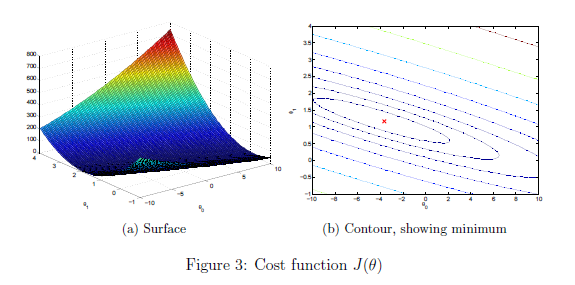

% Because of the way meshgrids work in the surf command, we need to 
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f,\n%f',theta(1),theta(2),theta(3))

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================
predictP = [1650 3];
featureN

price = [theta(1)+ theta(2) * 1650 + theta(3) * 3]; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

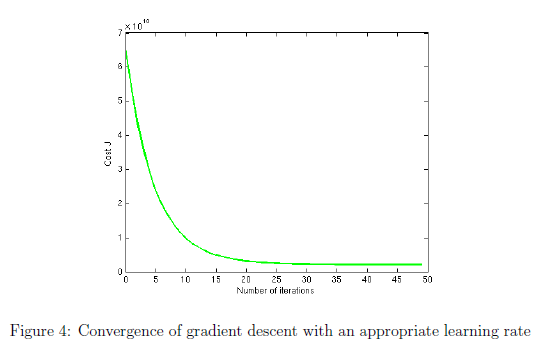

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 0.3;
num_iters = 50;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 1;
num_iters = 400;

% Init Theta and Run Gradient Descent 
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f',theta(1),theta(2))

% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f', theta(1),theta(2));

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house. 
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);     

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

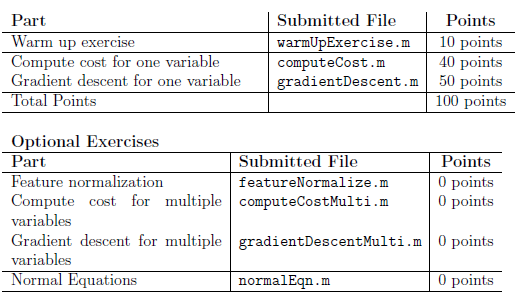

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.